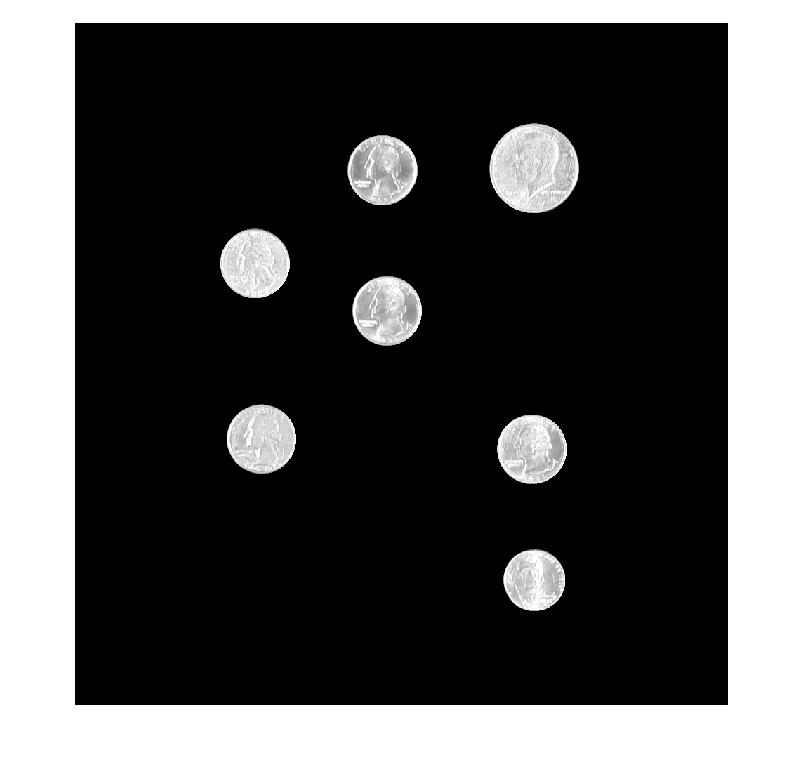

testCoinImage = imread("testCoinImage1.png");
% Assuming testCoinImage, testCoinMask, and segmentCoins are already defined
[testCoinMask,maskedCoinImage] = segmentCoins(testCoinImage);
% Generate the coin edge mask
maksedEdges = edge(maskedCoinImage);
se = strel('disk', 10);
erodedMask = imerode(testCoinMask, se);
faceEdgeMask = maksedEdges & erodedMask;

% Expand the edge mask and combine it with the foreground mask
expandedEdgeMask = imdilate(faceEdgeMask, strel('disk', 30));  % Expand edges
validCoinMask = expandedEdgeMask & testCoinMask;

% Mask the image to show only valid coins
finalMaskedImage = maskedCoinImage;  % Start with the masked image
finalMaskedImage(~validCoinMask) = 0;  % Set non-coin regions to 0 (black)
imshow(finalMaskedImage)


% Extract the area of each valid coin
coinSizes = regionprops("table", validCoinMask, "Area");
length(coinSizes.Area)

ans = 7

% % Plot the histogram of coin areas to check the distribution
% figure;
% histogram(coinSizes.Area, 20);  % Adjust the number of bins if necessary
% coinSizes;
% Classify coins based on area thresholds (adjust thresholds as needed)
nDimes = length(coinSizes(coinSizes.Area <= 6000,:).Area);
nNickels = length(coinSizes(6000 < coinSizes.Area & coinSizes.Area <= 7000,:).Area);
nQuarters = length(coinSizes(7000 < coinSizes.Area & coinSizes.Area <= 8000,:).Area);
nFiftyCents = length(coinSizes(8000 < coinSizes.Area,:).Area);

% Calculate total USD value based on coin counts
USD = nDimes * 0.1 + nNickels * 0.05 + nQuarters * 0.25 + nFiftyCents * 0.5;

% Display results
fprintf('Dimes: %d\n', nDimes);

Dimes: 0


fprintf('Nickels: %d\n', nNickels);

Nickels: 1


fprintf('Quarters: %d\n', nQuarters);

Quarters: 5


fprintf('Fifty Cents: %d\n', nFiftyCents);

Fifty Cents: 1


fprintf('Total Value: $%.2f\n', USD);

Total Value: $1.80



function [BW,maskedImage] = segmentCoins(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 11-Feb-2025
%----------------------------------------------------


% Adjust data to span data range.
X = imadjust(X);

% Find circles
[centers,radii,~] = imfindcircles(X,[25 75],'ObjectPolarity','bright','Sensitivity',0.85);
max_num_circles = Inf;
if max_num_circles < length(radii)
    centers = centers(1:max_num_circles,:);
    radii = radii(1:max_num_circles);
end
BW = circles2mask(centers,radii,size(X,1:2));

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end